format long
syms x_l f_l f_d(s,t,z) g_d(s,t,z)

% import the data we have 
data = importdata('FP_data_Q4.txt');
x = data(:,1);
y = data(:,2);

% set the step size 
h = 0.125;

% interpolate more points
% find the lagrange function to interpolate more points
f_l = LagrangePolynomial(x_l,x,y)

$$L\_coeffs = \left(\begin{array}{c} \frac{128\,\left(2\,x_{l}-1\right)\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{315}\\ -\frac{256\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{15}\\ \frac{512\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{9}\\ -\frac{256\,x_{l}\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{3}\\ \frac{1024\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{15}\\ -\frac{256\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)\,\left(x_{l}-\frac{7}{4}\right)}{9}\\ \frac{512\,x_{l}\,\left(x_{l}-1\right)\,\left(x_{l}-\frac{1}{2}\right)\,\left(x_{l}-\frac{3}{2}\right)\,\left(x_{l}-\frac{3}{4}\right)\,\left(x_{l}-\frac{5}{4}\right)}{105} \end{array}\right)$$

$$f\_l = -\frac{715712\,{x_{l}}^{6}}{196875}+\frac{1486312\,{x_{l}}^{5}}{65625}-\frac{2145226\,{x_{l}}^{4}}{39375}+\frac{1629949\,{x_{l}}^{3}}{26250}-\frac{50029729\,{x_{l}}^{2}}{1575000}+\frac{4304413\,x_{l}}{1050000}+1$$

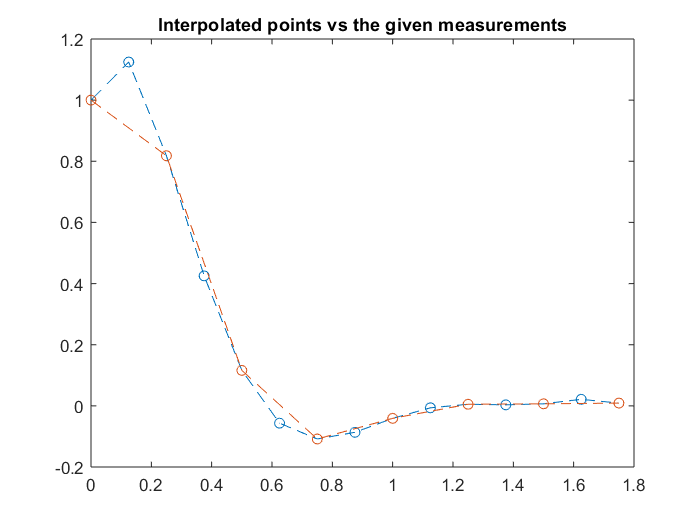

% put the new point back into the points 
x = [x(1:2-1); 0.25; x(2:end)];
y = [y(1:2-1); double(subs(f_l,x_l,0.25)); y(2:end)];

% interpolate new set of points
x_new = [x(1):h:x(length(x))];
y_new = zeros(length(x_new),1);

% calculate the new points that will be
for i=1:length(x_new)
    % for all the points we already have just insert them in
    if rem(x_new(i),0.25) == 0
        y_new(i) = y(find(x==x_new(i)));
    end
    y_new(i) = double(subs(f_l,x_l,x_new(i)));
end

% plot the new points vs the old 
plot(x_new,y_new,'--o')
hold on
plot(x,y,'--o')
title('Interpolated points vs the given measurements')
hold off

% initialize the matrices for the system of equations 
B = [1;1;1];
A = zeros(3);

% find the inputs to the matrix using hte 8th order central difference
count = 0;
for i=5:10
    cd_1 = (y_new(i-4)/280 - y_new(i-3)*4/105 + y_new(i-2)/5 - y_new(i-1)*4/5 + y_new(i+1)*4/5 - y_new(i+2)/5 + y_new(i+3)*4/105 - y_new(i+4)/280)/h;
    cd_2 = (-y_new(i-4)/560 + y_new(i-3)*8/315 - y_new(i-2)/5 + y_new(i-1)*8/5 - y_new(i)*205/72 + y_new(i+1)*8/5 - y_new(i+2)/5 + y_new(i+3)*8/315 - y_new(i+4)/560)/h^2; 
    row = rem(count,3) + 1;
    
    % take the average of the central calculated central difference and the
    % points if they are next to each other 
    if rem(count,2)
        A(row,1) = (A(row,1)+cd_2)/2;
        A(row,2) = (A(row,2)+cd_1)/2;
        A(row,3) = (A(row,3)+y_new(i))/2;
    else 
        A(row,1) = cd_2;
        A(row,2) = cd_1;
        A(row,3) = y_new(i); 
    end
    count = count + 1;
end

% find the coefficients 
coeffs = inv(A)*B

coeffs = 	1.0e+02 *

   0.033586704235173
   0.225951996658204
   1.010425447721065


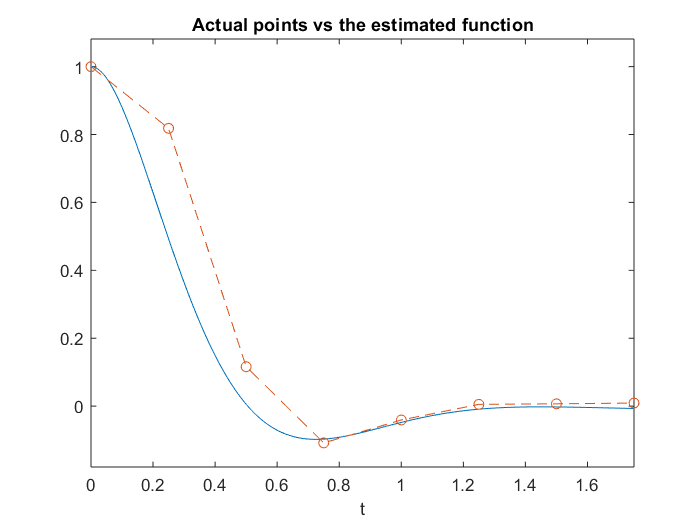

% find the function of ode in order to plot it
syms y_d(t)
coeffs = coeffs*-1;
Dy = diff(y_d);
D2y = diff(y_d,2);

ode = coeffs(1)*D2y + coeffs(2)*Dy + coeffs(3)*y_d == 1;
ySol = dsolve(ode,y_d(0)==1,Dy(0)==0);

% plot the calculated function vs the points
ezplot(ySol,[0,1.75])
hold on 
plot(x,y,'--o')
title('Actual points vs the estimated function')
hold off